# Sistemas Realimentados - 2023/2

## Nome: Gabrielly Barcelos Cariman

## Data limite para entrega: 8/11, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- Não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entreguem no prazo o que estiver pronto.

## Trabalho 4 - Análise da resposta em frequência

I=14; % Seu valor de I
[nyq1,nyq2]=ini_t4(I);
datetime('now')

ans = datetime
   08-Nov-2023 12:02:19


## Atividade 1: Análise de gráficos de Bode

O gráfico de Bode abaixo contém ganhos, polos e zeros, todos afastados de pelo menos uma década.

1.1 Obtenha a função de transferência no formato $G(s)=K\frac{(1+sz_1)(1+sz_2)...}{(1+sp_1)(1+sp_2)...}$ e refaça o gráfico de Bode para verificar se está igual ao fornecido.

Resposta:

Como o gráfico de magnitude permanece decrescente em praticamente todos os pontos, isso mostra que existe apenas um zero e 4 pólos na função.

Todas as frequências mencionadas no texto estão na unidade de radianos por segundo (rad/s).

Portanto, a partir do gráfico, é possível observar a presença de polos na origem por iniciar com fase de -90 graus e magnitude decrescendo 20 dB por década;

Entre as frequências de 0.01 e 1, a fase varia de -90 para um valor um pouco menor que -225 e, em seguida, atinge um valor ligeiramente superior a -225, resultando em uma variação aproximada de 135 graus. Simultaneamente, a magnitude apresenta um decaimento aproximado de 40 dB por década. Essa variação na fase sugere a presença de dois polos, um localizado na frequência 0.01 e outro em 1, juntamente com um zero na frequência 0.1, entre os polos. Essa configuração faz com que a magnitude não decaia a uma taxa de 60 dB por década e leva a uma leve elevação próxima a -225 na fase;

Após essa variação de fase, esta se estabiliza em um valor constante de -270 graus, variando 45 graus entre -225 e -270. Isso ocorre devido à presença de outro polo na frequência 10. A coexistência do zero em 0.1 e do polo próximo na frequência 10 reduz as variações de fase que normalmente seriam de 90 graus. Quanto à magnitude, ela começa a decrescer a uma taxa de 60 dB por década após essa frequência.

Dado que o gráfico da magnitude começou deslocado em aproximadamente 50 dB.

E o módulo é dado por 20log10(k)

Temos para 50dB:

50 = 20log10(G(jw)) 

G(jw) = $100\sqrt{10}$

G(jw) = K* (zero)/(polos)

K* (zero)/(polos)(jw) = $100\sqrt{10}$

K = $100\sqrt{10}$*(polos/zeros)(jw)

A frequência inicial é:

frequencia = 0.001

frequencia = 1.0000e-03

K = 100*sqrt(10)*((0+frequencia)*(100+frequencia)*(1+frequencia)*(0.1+frequencia)/(10+frequencia))

K = 0.3197

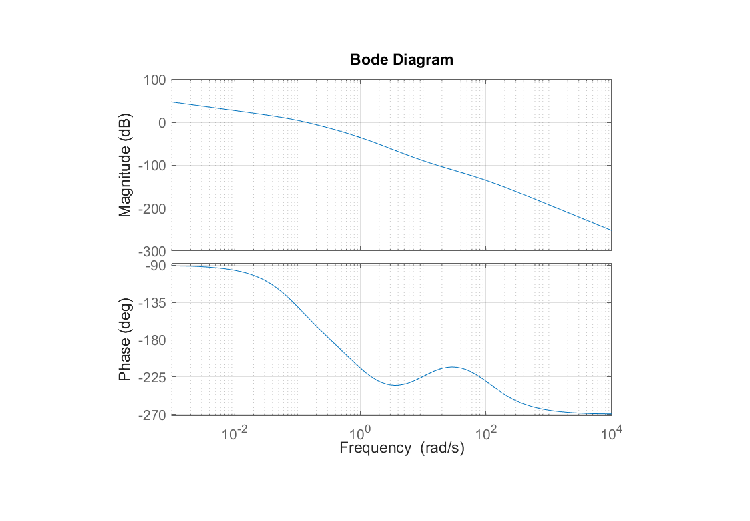

figure
imshow('fig1.png');

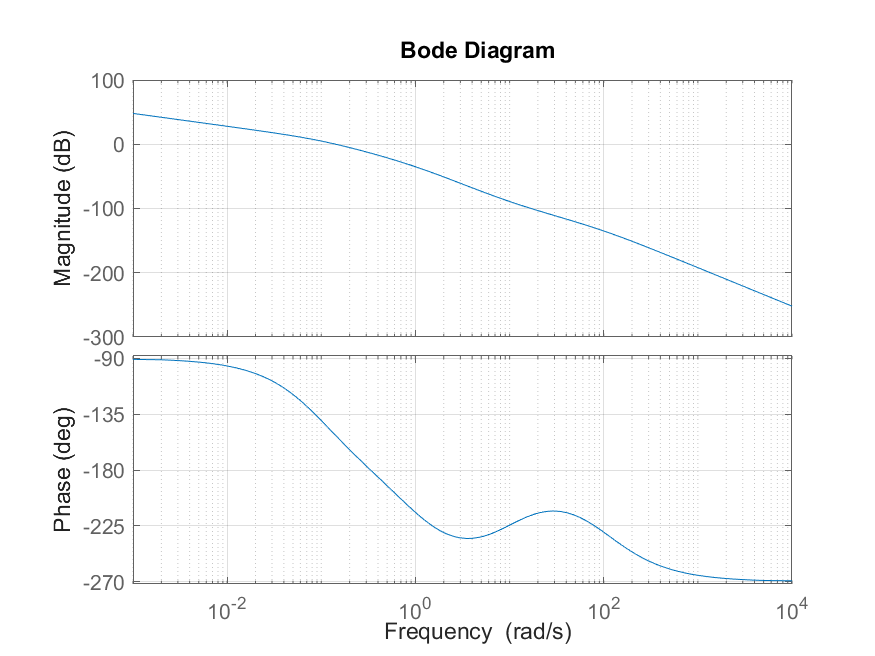

Obtendo a função de transferência:

s = tf('s');
G1 = K*(1+s*0.1)/(s*(1+s*0.01)*(1+s*1)*(1+s*10))

G1 =
 
          0.03197 s + 0.3197
  -----------------------------------
  0.1 s^4 + 10.11 s^3 + 11.01 s^2 + s
 
Continuous-time transfer function.
Model Properties


Gráfico de Bode igual ao fornecido:

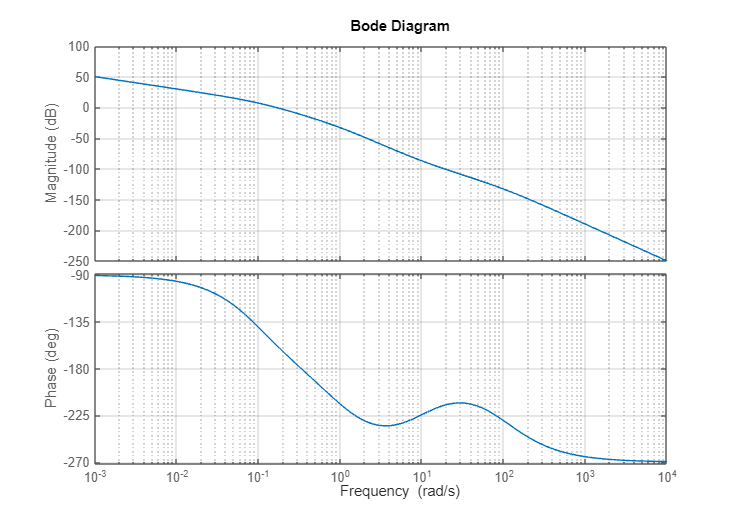

frequencias = logspace(-3, 4, 100);
bode(G1, frequencias);
grid on;

1.2 Obtenha as margens de fase e de ganho.

Resposta:

Margem de ganho: O ganho que deve ser adicionado ao sistema (em dB) para que o mesmo se torne instável. 

Portanto, antes de calcular as margens de estabilidade, é importante verificar se o sistema é estável ou instável usando o critério de Nyquist.

O critério de estabelildade de Nyquist é dado por: $\phi =\left(Z_d -P_d -\;\frac{P_w }{2}\right)*180$

Em que:

 Zd são os zeros no SPD em malha fechada

Pw são os polos na origem em malha aberta

Pd são os polos no SPD em malha aberta

$\phi$ é o ângulo da função em torno do ponto -1 quando a frequência varia de infinito a zero.

Portanto, para calcular o $\phi$ para que o sistema seja estável, temos:

Zd = 0; Pw = 1 e Pd = 0. Assim, $\phi$ = -90 graus

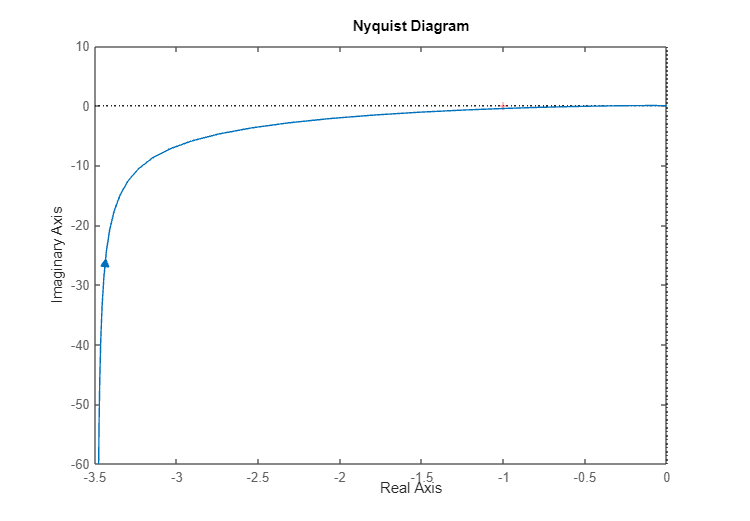

h=nyquistplot(G1);
set(h,'ShowFullContour','off')

A partir do gráfico apresentado, é possível observar que o ponto em que o gráfico toca o eixo ocorre após -1.

Como o gráfico não envolve o ponto -1, a fase ($\phi$) é de -90 graus, o que indica que o sistema é estável.

Portanto, com base no critério de Nyquist, podemos concluir que o sistema é estável.

Agora que confirmamos que o sistema é estável com base no critério de Nyquist, podemos prosseguir e calcular as margens de estabilidade.

O ponto -1 corresponde, no diagrama de Bode, ao ponto (0dB, -180 graus)

Margem de ganho(MG): 

O ganho que deve ser adicionado ao sistema (em dB) para que o mesmo se torne instável;

A Margem de Ganho é obtida verificando a frequência na qual a fase cruz o eixo de 180 graus.

Margem de Fase (MF):

O ângulo que a curva de G( jω) deve ser rotacionada (no sentido horário) de  modo que a mesma cruze o ponto –1;

A Margem de Fase é obtida verificando a frequência na qual o módulo cruza o eixo de 0dB.

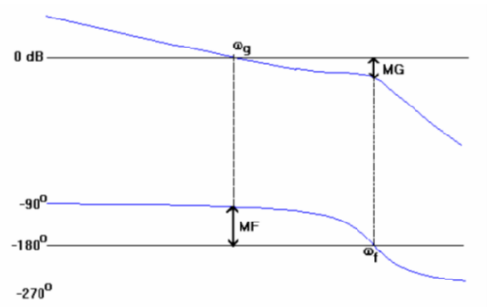

Verificando o gráfico de Bode:

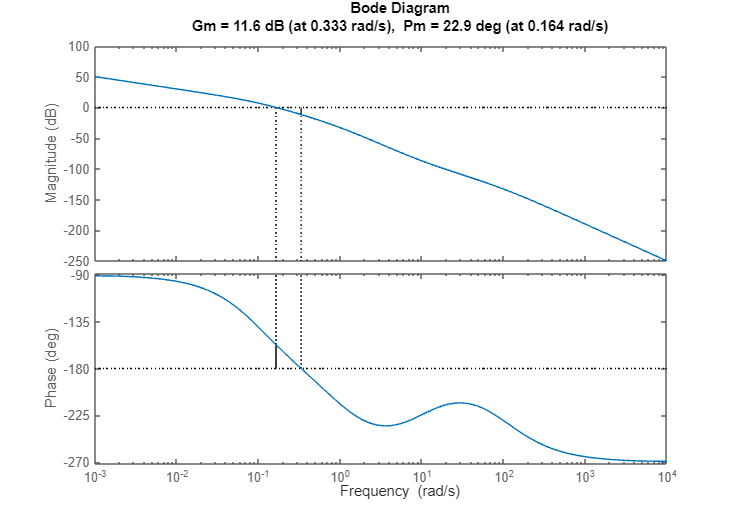

margin(G1)

É possível observar no gráfico que a margem de ganho é, de fato, aproximadamente 10dB, o que está em concordância com o resultado obtido pelo MATLAB.

Isso porque, faltam aproximadamente 10 dB para a magnitude chegar em 0 dB na mesma frequência em que a fase é -180 graus.

Para 10dB:

10 = 20log10(x) 

x = $\sqrt{10}$

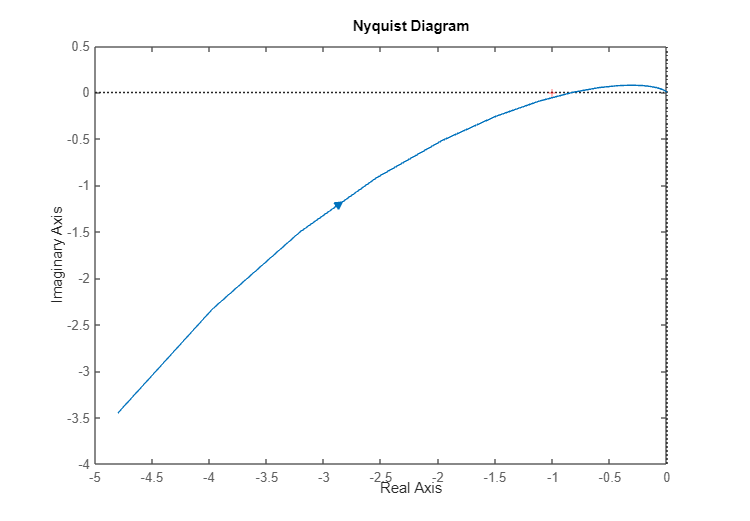

h=nyquistplot(sqrt(10)*G1);
set(h,'ShowFullContour','off');
xlim([-5,0]);

Assim, como a margem de ganho, a margem de fase também foi corretamente calculada como aproximadamente 30 graus como pode ser obervado no grafico.

Isso porque, faltam aproximadamente 30 graus para a fase chegar em -180 graus na mesma frequência em que magnitude é 0 dB.

## Atividade 2: Critério de Nyquist

Seja o gráfico de Nyquist abaixo de $G(s)=\frac{K}{s(s+a)(s+b)}$, $a>0, b>0$. desenhado com $K=1.$

nyq1

nyq1 = -0.7000

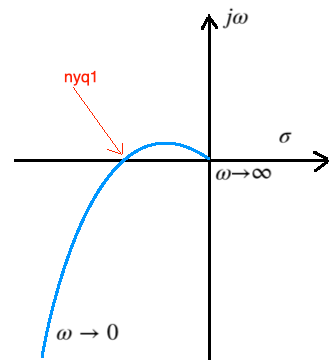

2.1 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura (imshow). 

Resposta:

O critério de estabelildade de Nyquist é dado por: $\phi =\left(Z_d -P_d -\;\frac{P_w }{2}\right)*180$

Em que:

 Zd são os zeros no SPD em malha fechada

Pw são os polos na origem em malha aberta

Pd são os polos no SPD em malha aberta

$\phi$ é o ângulo da função em torno do ponto -1 quando a frequência varia de infinito a zero.

Portanto, para calcular o $\phi$ para que o sistema seja estável, temos:

Zd = 0; Pw = 1 e Pd = 0. Assim, $\phi$ = -90 graus

Existem duas situações possíveis. A primeira é a de estabilidade, na qual o (nyq1) é menor que -1, e o gráfico não envolve o -1. Nessa situação, o ângulo ($\phi$) seria de -90 graus, indicando que o sistema é estável.

A segunda situação ocorre quando o  (nyq1) é maior que -1, e o gráfico envolve o -1. Nesse caso, o ângulo ($\phi$) seria de +270 graus, sinalizando que o sistema é instável.

Como nyq1 = -0.7, portanto ele é menor que -1, o gráfico não irá envolver o -1 e o sistema é estável.

2.2 Obtenha os valores de $K\in[-\infty, \infty]$ para que esse sistema seja estável, esboçando o gráfico de Nyquist para K negativo.

Resposta:

Para K > 0:

O sistema é estável quando o valor de nyq1 é menor que -1. Nesse caso, temos nyq1 = -0.7. Portanto, ao dividir -1 por -0.7, obtemos:

K = -1/nyq1

K = 1.4286

Dessa forma, é necessário que K seja menor do 1.4286 para que o sistema permaneça estável e não cruze a marca de -1.

Isso ocorre porque, quando o ganho é igual a 1.4286 (1 dividido por -0,7), o gráfico atinge o ponto -1. Portanto, o valor de K precisa ser menor que 1.4286 para que o sistema permaneça estável e não envolv -1:

ponto = K*nyq1

ponto = -1

Para K < 0:

Para esboçar o gráfico de Nyquist para valores de K negativos, é necessário realizar um giro de 180 graus no gráfico original ou espelhar na origem, que é construído para K > 0.

Dessa forma, o gráfico para K < 0 seria da seguinte maneira:

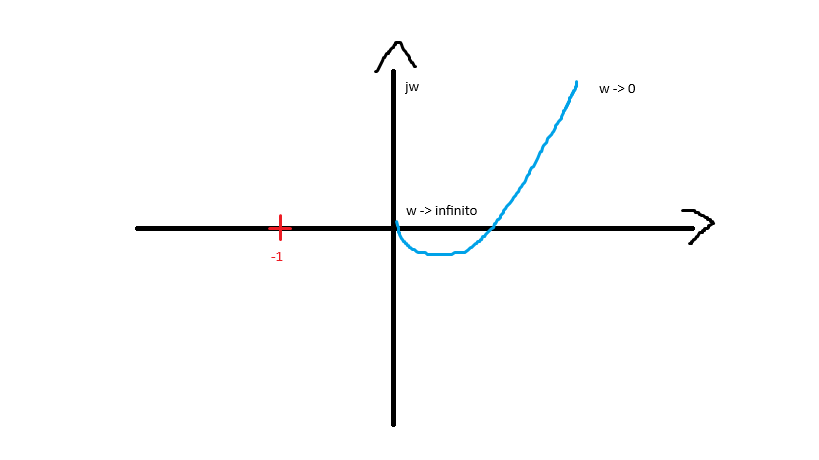

Analisando o gráfico para ganhos negativos, é possível perceber que, o valor de não K será alterado para manter a estabilidade.

Portanto, K < 1.4286

Seja agora o gráfico de $G(s)=\frac{K(s+a)^2}{s^3}$, $a>0$, desenhado com $K=1.$

nyq2

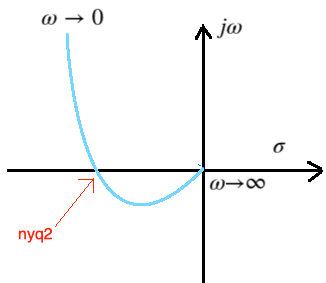

2.3 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura. 

Resposta:

O critério de estabelildade de Nyquist é dado por: $\phi =\left(Z_d -P_d -\;\frac{P_w }{2}\right)*180$

Em que:

 Zd são os zeros no SPD em malha fechada

Pw são os polos na origem em malha aberta

Pd são os polos no SPD em malha aberta

$\phi$ é o ângulo da função em torno do ponto -1 quando a frequência varia de infinito a zero.

Portanto, para calcular o $\phi$ para que o sistema seja estável, temos:

Zd = 0; Pw = 3 e Pd = 0. Assim, $\phi$ = -270 graus

Existem duas situações possíveis. A primeira é a de estabilidade, na qual o (nyq2) é menor que -1, e o gráfico não envolve o -1. Nessa situação, o ângulo ($\phi$) seria de +90 graus, indicando que o sistema é instável.

A segunda situação ocorre quando o  (nyq2) é maior que -1, e o gráfico envolve o -1. Nesse caso, o ângulo ($\phi$) seria de -270 graus, sinalizando que o sistema é estável.

Como nyq2 = -1.2, portanto ele é maior que -1, o gráfico irá envolver o -1 e o sistema é estável.

2.4 Obtenha os valores de $K\in[-\infty, \infty]$ para que esse sistema seja estável.

Resposta:

Para K > 0:

O sistema é estável quando o valor de nyq2 é maior que -1. Nesse caso, temos nyq2 = -1.2. Portanto, ao dividir -1 por -1.2, obtemos:

K = -1/nyq2

nyq2 = -1.2000

Dessa forma, é necessário que K seja maior do 0.8333 para que o sistema permaneça estável e envolva o -1.

Isso ocorre porque, quando o ganho é igual a 0.8333 (1 dividido por -1.2), o gráfico atinge o ponto -1. Portanto, o valor de K precisa ser maior que 1.4286 para que o sistema permaneça estável e envolva -1:

ponto = K*nyq2

K = 0.8333

Para K < 0:

Para esboçar o gráfico de Nyquist para valores de K negativos, é necessário realizar um giro de 180 graus no gráfico original ou espelhar ele na origem, que é construído para K > 0.

Dessa forma, o gráfico para K < 0 seria da seguinte maneira:

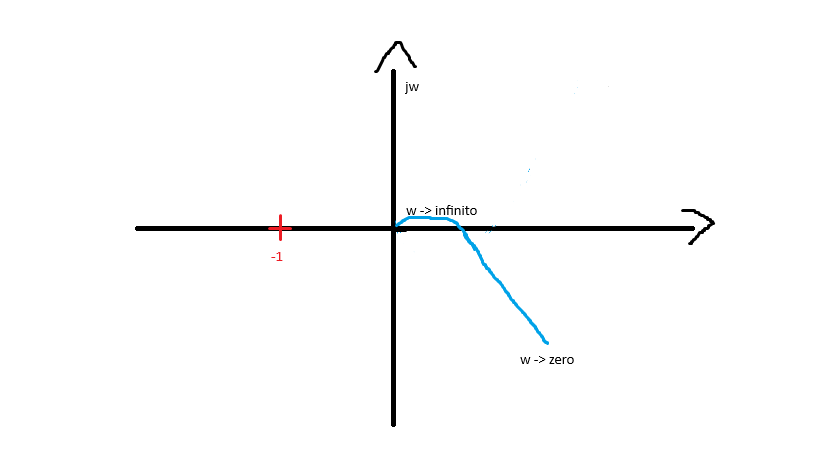

Analisando o gráfico para ganhos negativos, é possível perceber que, o valor de não K será alterado para manter a estabilidade.

Portanto, K < 1.4286

Analisando o gráfico para ganhos negativos, é possível perceber que, o valor de não K será alterado para manter a estabilidade.

Portanto, K > 0.8333

## Atividade 3: Efeito do ganho na estabilidade relativa.  

3.1 Use o método do lugar das raízes para ver o efeito do ganho nas margens de fase e ganho usando G1 da atividade 1, comparando o efeito do ganho sobre o amortecimento e sobre a margem de fase. Dica: rltool permite ver o LR (amortecimento) e gráfico de Bode (Margens).

%rltool(G1)

Resposta:

Verificando valores:

Ganho bem pequeno de 0.07:

O amortecimento e margem de ganho e fase são grandes 

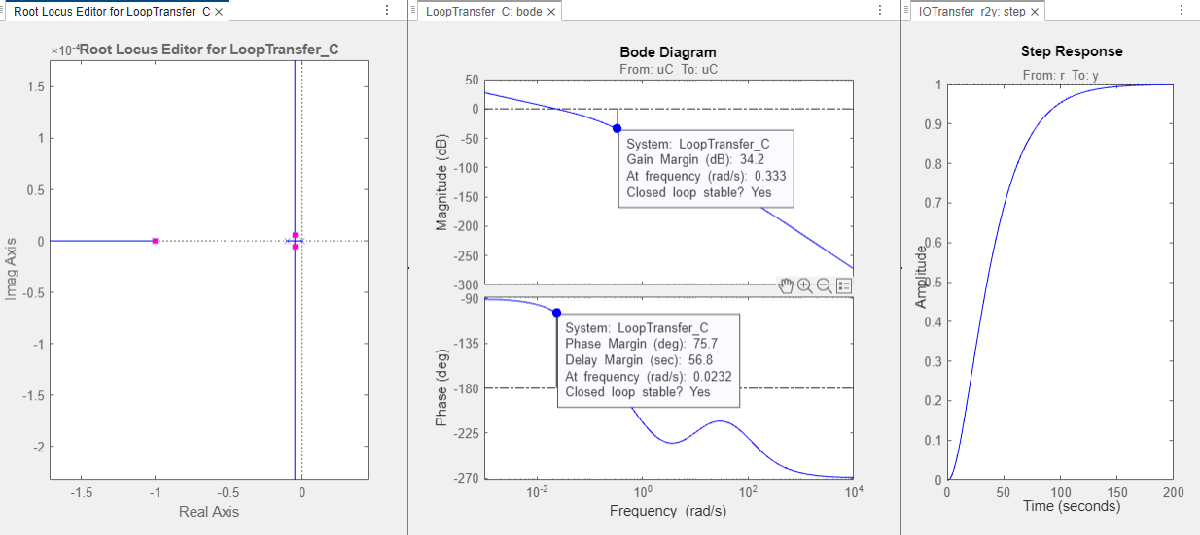

Ganho grande de 2.5384:

O amortecimento e margem de ganho e fase são pequenos 

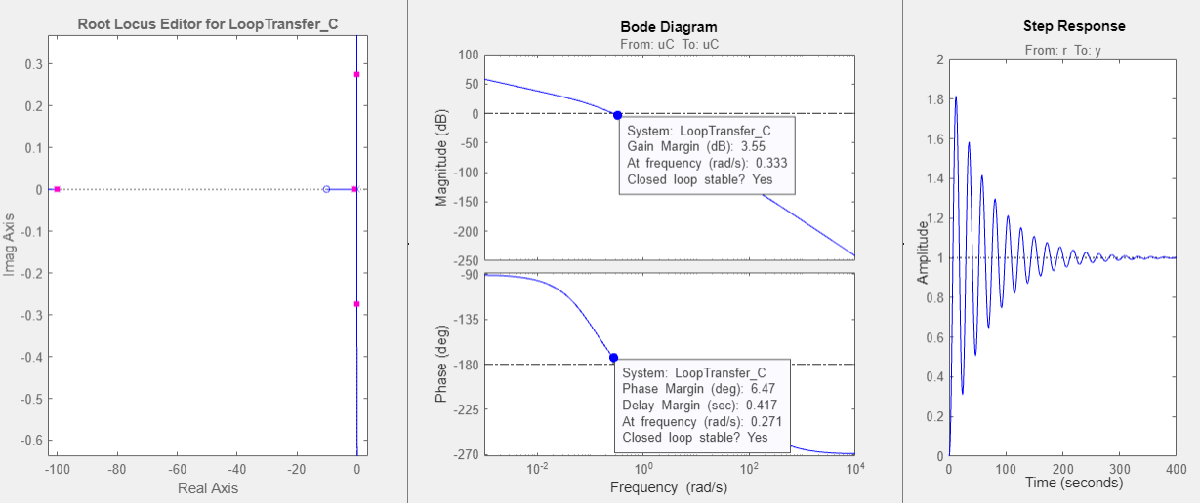

Comparando esses dois gráficos fica evidente que conforme o ganho aumenta, o sistema se torna mais oscilatório, diminuindo o amortecimento e as margens de ganho e fase. Pelo fato de um sistema mais oscilatório estar mais perto de se tornar um sistema instável.

3.2 Escolha um ganho K tal que a margem de fase seja aproximadamente 10 graus, mostrando o LR e o gráfico de Bode para este ganho K. Qual a margem de ganho ?

Resposta:

O ganho de 2.0407 tem margem de fase de 10.1 graus e margem de fase de 5.44 dB.

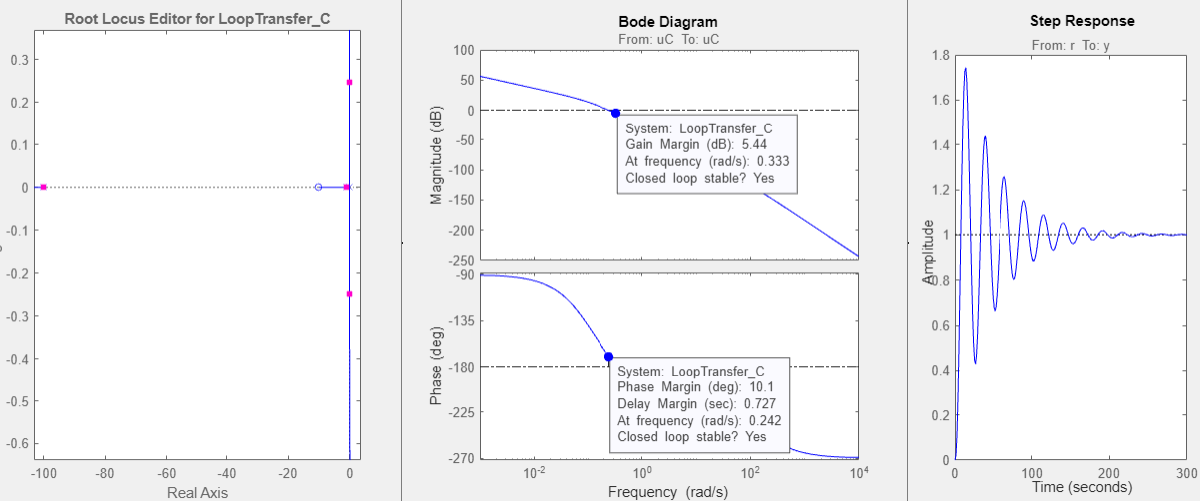

## Atividade 4: Efeito de um atraso de tempo na estabilidade relativa. 

4.1 Obtenha o atraso de tempo tal que G1 com este atraso tenha margem de fase nula.  Plote então o gráfico de Bode de G1 com e sem o atraso, verificando a margem de fase e de ganho nos dois casos.

Resposta:

A Margem de Fase (MF) é obtida verificando a frequência na qual o módulo cruza o eixo de 0dB.

Verificando o quanto falta para chegar em -180 graus.

Portanto, para obter margem de fase nula é necessário que na frequência na qual o módulo cruza o eixo de 0dB, o ângulo seja 180 graus. 

Para fazer isso, será colocado um atraso na função de transferência.

margin(G1)

ponto = -1

Como pode ser visto, para G1 a margem de ganho é de 11.6 dB e a margem de fase é de 22.9 graus.

O máximo atraso d é dado em segundos por:


$$d=\frac{\pi \;\mathrm{MF}}{180\;\omega }$$


Em que:

MF =  Margem de Fase

w =  Frequência na qual o módulo cruza o eixo de 0dB

MF = 22.9;
w = 0.164;
d = (pi*MF)/(180*w)

Adicionando o atraso:

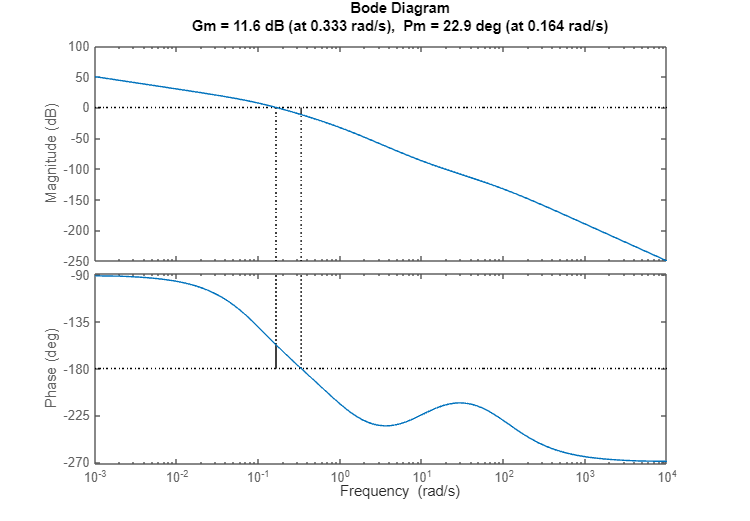

s = tf('s');

G1_atrasada = G1 * exp(-d*s)

 Gráfico de Bode de G1 com atraso:

margin(G1_atrasada)

De fato, a margem de fase e de ganho deram aproximadamente zero, como pode ser visto no gráfico acima.

Gráfico de Bode de G1 sem atraso:

d = 2.4371

G1_atrasada =
 
                         0.03197 s + 0.3197
  exp(-2.44*s) * -----------------------------------
                 0.1 s^4 + 10.11 s^3 + 11.01 s^2 + s
 
Continuous-time transfer function.
Model Properties


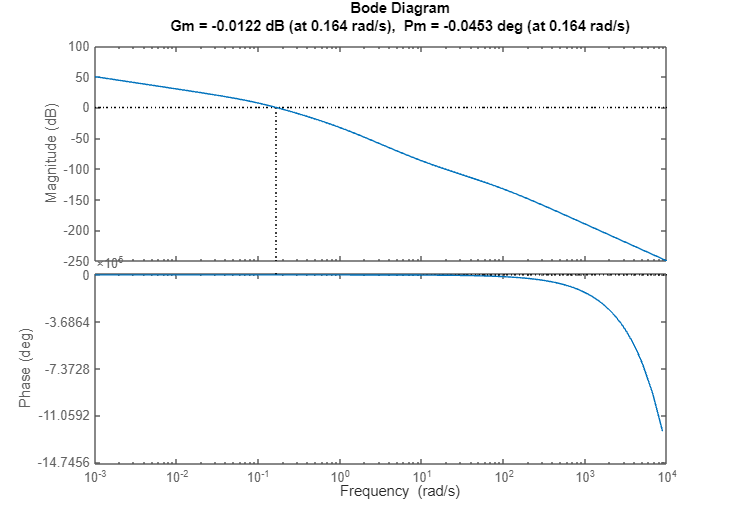

margin(G1)

Muito diferente da função original em que a margem de fase é 22.9 graus e a margem de ganho é 11.6 dB.